clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[0;21.683;5.678];
u31=[0;0;1];
r2=[0;21.683;1.816];
u32=[0;0;-1];
r3=[0;21.683;13.053];
u33=[0;0;-1];
r4=[18.778;32.524;1.935];
u34=[0;0;1];
r5=[18.778;32.524;9.310];
u35=[0;0;-1];
r6=[18.778;10.841;5.559];
u36=[0;0;-1];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];

hold on
axis([0 15 0 15]);
for R1=2:0.3:13 %离心率
    R3=2;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     2.0000    1.9000    1.0329


ans =     2.3000    1.9000    1.0329


ans =     2.6000    1.9000    1.0329


ans =     2.9000    1.9000    1.0329


ans =     3.2000    1.9000    1.0329


ans =     3.5000    1.9000    1.0329


ans =     3.8000    1.9000    1.0329


ans =     4.1000    1.9000    1.0329


ans =     4.4000    1.9000    1.0329


ans =     4.7000    1.9000    1.0329


ans =     5.0000    1.9000    1.0329


ans =     5.3000    1.9000    1.0329


ans =     5.6000    1.9000    1.0329


ans =     5.9000    1.9000    1.0329


ans =     6.2000    1.9000    1.0329


ans =     6.5000    1.9000    1.0329


ans =     6.8000    1.9000    1.0329


ans =     7.1000    1.9000    1.0329


ans =     7.4000    1.9000    1.0329


ans =     7.7000    1.9000    1.0329


ans =     8.0000    1.9000    1.0329


ans =     8.3000    1.9000    1.0329


ans =     8.6000    1.9000    1.0329


ans =     8.9000    1.9000    1.0329


ans =     9.2000    1.9000    1.0329


ans =     9.5000    1.9000    1.0329


ans =     9.8000    1.9000    1.0329


ans =    10.1000    1.9000    1.0329


ans =    10.4000    1.9000    1.0329


ans =    10.7000    1.9000    1.0329


ans =    11.0000    1.9000    1.0329


ans =    11.3000    1.9000    1.0329


ans =    11.6000    1.9000    1.0329


ans =    11.9000    1.9000    1.0329


ans =    12.2000    1.9000    1.0329


ans =    12.5000    1.9000    1.0329


ans =    12.8000    1.9000    1.0329


 scatter(x1,y1,10,'markerfacecolor',[221, 42, 22]/256,...
        'markeredgecolor',[221, 42, 22]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','12')

 for R1=2:0.3:13 %离心率
    R3=2;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =     2.0000    3.6500    1.0207


ans =     2.3000    3.6500    1.0207


ans =     2.6000    3.6500    1.0207


ans =     2.9000    3.6500    1.0207


ans =     3.2000    3.6500    1.0207


ans =     3.5000    3.6500    1.0207


ans =     3.8000    3.6500    1.0207


ans =     4.1000    3.6500    1.0207


ans =     4.4000    3.6500    1.0207


ans =     4.7000    3.6500    1.0207


ans =     5.0000    3.6500    1.0207


ans =     5.3000    3.6500    1.0207


ans =     5.6000    3.6500    1.0207


ans = 1×3
    5.9000    3.6500    1.0207


ans = 1×3
    6.2000    3.6500    1.0207


ans = 1×3
    6.5000    3.6500    1.0207


ans = 1×3
    6.8000    3.6500    1.0207


ans = 1×3
    7.1000    3.6500    1.0207


ans = 1×3
    7.4000    3.6500    1.0207


ans = 1×3
    7.7000    3.6500    1.0207


ans = 1×3
    8.0000    3.6500    1.0207


ans = 1×3
    8.3000    3.6500    1.0207


ans = 1×3
    8.6000    3.6500    1.0207


ans = 1×3
    8.9000    3.6500    1.0207


ans = 1×3
    9.2000    3.6500    1.0207


ans = 1×3
    9.5000    3.6500    1.0207


ans = 1×3
    9.8000    3.6500    1.0207


ans = 1×3
   10.1000    3.6500    1.0207


ans = 1×3
   10.4000    3.6500    1.0207


ans = 1×3
   10.7000    3.6500    1.0207


ans = 1×3
   11.0000    3.6500    1.0207


ans = 1×3
   11.3000    3.6500    1.0207


ans = 1×3
   11.6000    3.6500    1.0207


ans = 1×3
   11.9000    3.6500    1.0207


ans = 1×3
   12.2000    3.6500    1.0207


ans = 1×3
   12.5000    3.6500    1.0207


ans = 1×3
   12.8000    3.6500    1.0207


 scatter(x2,y2,10,'markerfacecolor',[29, 50, 67]/256,...
        'markeredgecolor',[29, 50, 67]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','13')

for R1=11:0.3:15 %离心率
    R3=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
   11.0000   11.0500    1.0000


ans = 1×3
   11.3000    6.6000    1.0009


ans = 1×3
   11.6000    5.2500    1.0006


ans = 1×3
   11.9000    4.5000    1.0030


ans = 1×3
   12.2000    4.0500    1.0032


ans = 1×3
   12.5000    3.7500    1.0013


ans = 1×3
   12.8000    3.5000    1.0033


ans = 1×3
   13.1000    3.3000    1.0065


ans = 1×3
   13.4000    3.1500    1.0076


ans = 1×3
   13.7000    3.0500    1.0027


ans = 1×3
   14.0000    2.9500    1.0021


ans = 1×3
   14.3000    2.8500    1.0060


ans = 1×3
   14.6000    2.7500    1.0145


ans = 1×3
   14.9000    2.7000    1.0099


 scatter(x3,y3,10,'markerfacecolor',[84, 130, 53]/256,...
        'markeredgecolor',[84, 130, 53]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','14')

for R1=11:0.3:15 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];   
end

ans = 1×3
   11.0000   10.7000    1.0002


ans = 1×3
   11.3000    6.4000    1.0010


ans = 1×3
   11.6000    5.1000    1.0003


ans = 1×3
   11.9000    4.4000    1.0003


ans = 1×3
   12.2000    3.9500    1.0010


ans = 1×3
   12.5000    3.6000    1.0067


ans = 1×3
   12.8000    3.4000    1.0027


ans = 1×3
   13.1000    3.2000    1.0070


ans = 1×3
   13.4000    3.0500    1.0091


ans = 1×3
   13.7000    2.9500    1.0052


ans = 1×3
   14.0000    2.8500    1.0057


ans = 1×3
   14.3000    2.7500    1.0109


ans = 1×3
   14.6000    2.7000    1.0038


ans = 1×3
   14.9000    2.6000    1.0173


 scatter(x4,y4,10,'markerfacecolor',[63, 125, 162]/256,...
        'markeredgecolor',[63, 125, 162]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','15')

 for R3=1:0.3:13 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];   
end

ans = 1×3
   10.8500    1.0000    1.0020


ans = 1×3
   10.8500    1.3000    1.0005


ans = 1×3
   10.8000    1.6000    1.0091


ans = 1×3
   10.8000    1.9000    1.0087


ans = 1×3
   10.8000    2.2000    1.0085


ans = 1×3
   10.8000    2.5000    1.0083


ans = 1×3
   10.8000    2.8000    1.0082


ans = 1×3
   10.8000    3.1000    1.0081


ans = 1×3
   10.8000    3.4000    1.0080


ans = 1×3
   10.8000    3.7000    1.0080


ans = 1×3
   10.8000    4.0000    1.0079


ans = 1×3
   10.8000    4.3000    1.0079


ans = 1×3
   10.8000    4.6000    1.0079


ans = 1×3
   10.8000    4.9000    1.0079


ans = 1×3
   10.8000    5.2000    1.0079


ans = 1×3
   10.8000    5.5000    1.0078


ans = 1×3
   10.8000    5.8000    1.0078


ans = 1×3
   10.8000    6.1000    1.0078


ans = 1×3
   10.8000    6.4000    1.0078


ans = 1×3
   10.8000    6.7000    1.0078


ans = 1×3
   10.8000    7.0000    1.0078


ans = 1×3
   10.8000    7.3000    1.0078


ans = 1×3
   10.8000    7.6000    1.0078


ans = 1×3
   10.8000    7.9000    1.0078


ans = 1×3
   10.8000    8.2000    1.0078


ans = 1×3
   10.8000    8.5000    1.0078


ans = 1×3
   10.8000    8.8000    1.0078


ans = 1×3
   10.8000    9.1000    1.0078


ans = 1×3
   10.8000    9.4000    1.0078


ans = 1×3
   10.8000    9.7000    1.0078


ans = 1×3
   10.8000   10.0000    1.0078


ans = 1×3
   10.8000   10.3000    1.0078


ans = 1×3
   10.8000   10.6000    1.0078


ans = 1×3
   10.8000   10.9000    1.0078


ans = 1×3
   10.8000   11.2000    1.0077


ans = 1×3
   10.8000   11.5000    1.0077


ans = 1×3
   10.8000   11.8000    1.0077


ans = 1×3
   10.8000   12.1000    1.0077


ans = 1×3
   10.8000   12.4000    1.0077


ans = 1×3
   10.8000   12.7000    1.0077


ans = 1×3
   10.8000   13.0000    1.0077


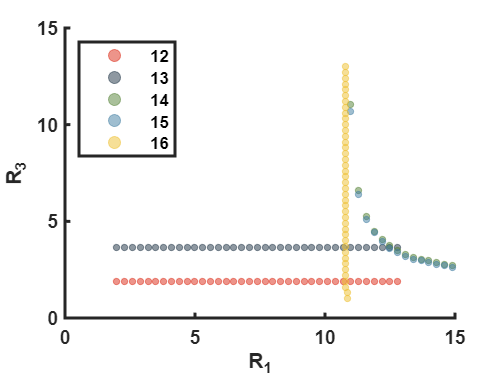

 scatter(x5,y5,10,'markerfacecolor',[239, 193, 48]/256,...
        'markeredgecolor',[239, 193, 48]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','16')

set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northwest');

hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end


